# Expand Example 2-21:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the convolution problem in Example 2.21.  Let $RC=1$.  The input signal is a unit pulse.  Express the factors $x(\lambda)$ and $h(t-\lambda)$ of the convolution integral as anonymous functions.  Graph them as $t$ is varied.

RC = 1;
lambda = [-3:0.01:3];
x = @(lambda) ss_step(lambda+0.5)-ss_step(lambda-0.5);
h = @(lambda) 1/RC*exp(-lambda/RC).*ss_step(lambda);

t = -0.6;

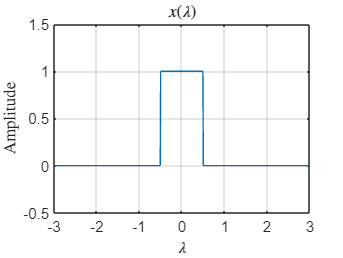

set(0,'defaultTextInterpreter','latex');
plot(lambda,x(lambda)); grid;
axis([-3,3,-0.5,1.5]);
xlabel('$\lambda$');
ylabel('Amplitude');
title('$x(\lambda)$');

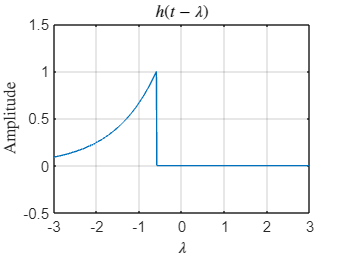

plot(lambda,h(t-lambda)); grid;
axis([-3,3,-0.5,1.5]);
xlabel('$\lambda$');
ylabel('Amplitude');
title('$h(t-\lambda)$');

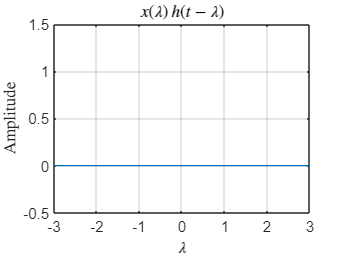

plot(lambda,x(lambda).*h(t-lambda)); grid;
axis([-3,3,-0.5,1.5]);
xlabel('$\lambda$');
ylabel('Amplitude');
title('$x(\lambda)\,h(t-\lambda)$');

set(0,'defaultTextInterpreter','tex');